# LECTURE WEEK VII. - HANDS-ON

# SIGNAL PROCESSING IN ACTION

**Objectives:**

- Experience the used of spectra/DFT in existing computer science applications.

- Learn how to extract relevant features from spectra/DFTs.

- Introduction to perceptual aspects of signal processing.

## Assignment VII.1: Music compression, the essence of MP3

**Completion requirements:**

- Explain and show how you select the L largest coefficients in assignment ***D***.

- Show plots of the retained non-­zero DFT coefficients (see assignment ***E***) for three different choices of $L$.

- Describe what value of $L$ gives an acceptable audio quality on the given audio sample.

- Explain to what extent the choice of $L$ affects audio quality on two different audio samples.

In this assignment, we explore the principles of today’s compression algorithms such as mp3, jpeg, and the different mpeg video compression standards. The fundamental observation in all compression methods is that if a signal (music, image, video) is represented in a spectral form (i.e. in the frequency transform domain), fewer transform coefficients are needed than samples in the original signal to get a good perceptual quality. In most compression standards, a variation on the DFT is used, namely the DCT or Discrete Cosine Transform. In this assignment, we will use the DFT/FFT for the purpose of simplicity.

***A.***

Read the music file “`data/musicclip.wav`” into the array `MM`, and listen to the 10 seconds of music. 

***Answer:***

What is the sampling frequency of the music?

***Answer:***

The first step is to break up the audio into short non-­overlapping segments (frames), so that we can process each frame independently. The frame length is typically 256 to 1024 samples. In this assignment we use as frame length of N=512 samples. How many milliseconds is a frame in this case?

For the purpose of computation efficiency, we put the frames of N samples into a matrix `XX(n,m)` of N rows by M columns. Each column then contains a frame, and the number of columns depends on the length of the signal (and the frame length). The following figure illustrates this operation.

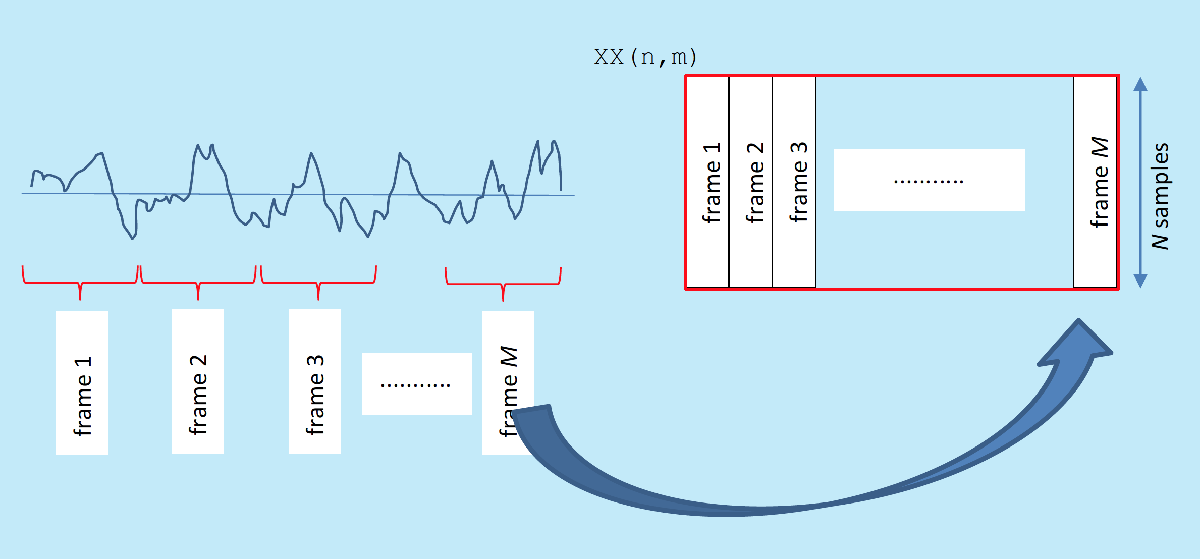

***B.*** Make use of a single `for`-­loop over the frames to convert the array `MM` into the `N`*x*`M` matrix `XX`. As an example, the second frame contains sample **513** to **1024**, and can be extracted in a single operation by the command: `XX(:,2)=MM(513:1024)`. After extraction of all frames you can verify if the conversion was correct by listening to the music row-­by-­row (frame-­by-­frame) using the command `sound(XX(:),Fs)`.

***Answer:***

***C.***

Using a single for-­loop, carry out the DFT/FFT on each of the rows/frames of `XX`. At this point we recommend putting the code as the function `compress(MM,L)` into an `.m` file, if you have not done so already. The purpose of the parameter `L` is explained below.

***Answer:***

We now have the signal available as a collection of spectra computed on a frame-­by-­frame basis. For each frame-­based spectrum we maintain only the **L** largest DFT coefficients in the range [0, $\pi$]. If, for instance, **L=16**, then we have achieved a compression of **N/L = 512/16 = 32** relative to the original signal.

***D.***

Find for each frame the **L** DFT coefficients that have the largest magnitude. Suitable MATLAB functions are, for instance, `[max,index]=max()` and `[y,index]=sort()`. Maintain only these **L** largest original DFT coefficients, and set all other DFT coefficients to zero. The result is stored in the `N`x`M` matrix `XXC`.

*Remember that the DFT of each frame has complex conjugated symmetry. Hence for the *$L$* largest DFT coefficients in [0, *$\pi$*] the corresponding L complex conjugated coefficients in the range [*$\pi$*,2*$\pi$*] must also be maintained in the matrix *`XXC`*.* See earlier MATLAB exercises and hands-­on assignments more details on complex conjugated symmetry and how the intervals [0,$\pi$] and [$\pi$,2$\pi$] are represented in the vector containing the DFT/FFT coefficients.

***Answer:***

We now have a compressed version of the music signal, where each frame in `XXC` is represented by only **L*** non-­zero DFT coefficients (plus the corresponding complex conjugated DFT values)*, rather than all original DFT coefficients.

***E.***

An easy way to visualize which non-­zero DFT coefficients are maintained is by using a pseudo-­color plot of the matrix `XXC`. Use the MATLAB command `pcolor(20*log10(abs(XXC(1:100,1:256))))` to display the first **100** DFT coefficients of the first **256** frames of the matrix `XXC`. Different pseudo-­colors indicate different magnitude/size of DFT coefficients in a frame. Study the effect of different values of **L**. 

***Answer:***

Where are the largest DFT coefficients usually located in the frames? Are the same DFT coefficients selected in each frame?

***Answer:***

***F.***

Carry out an inverse DFT/FFT on each frame, yielding the **N**x**M** matrix `YY`. Obviously this is nearly the same code structure as in part ***C.***, now executing an inverse DFT. Listen to the resulting compressed music using the command `sound(YY(:),Fs)` for different values of **L**. Determine which value of $L$ gives an acceptable audio quality.

***Answer:***

***G.***

Use the compression method that you have implemented in this assignment on other music files (some are provided in the data set, or you can bring your own music samples), and on the short speech segment ‘`data/welkom.wav`’. Study the effect on the quality of setting different values of $L$.

***Answer:***

**Completion requirements:**

- Explain and show how you select the L largest coefficients in assignment ***D***.

- Show plots of the retained non-­zero DFT coefficients (see assignment ***E***) for three different choices of $L$.

- Describe what value of $L$ gives an acceptable audio quality on the given audio sample.

- Explain to what extent the choice of $L$ affects audio quality on two different audio samples.

## MATLAB Assignment VII.2: Music identification, at the core of Shazam & more

**Completion requirements:**

- Show the fingerprints (as requested in assignment ***E***) for one of the given music samples.

- Explain which song was represented in "`data/fingerprint.mat``"`. Show the BER for each of the music clips in relation to the unknown music clip.

- Explain how you would set a BER threshold to recognize a song in the given dataset.

In this assignment you will implement the basics of on-­line music identification services such as Shazam, SoundHound, Tunatic, and Nabbit. Music identification is based on comparing the spectrum of the query music to a database of spectra of known songs. The best matching spectrum determines which song is identified. On-­line music identification often involves identifying songs independently of the specific recording device, performance, artist, or even version of the song. Here, we will focus on the problem that involves different versions of the same reference recording.

Like the compression in previous Assignment, music identification is based on processing short frames of music. The way these frames are selected and which frequencies are represented in the spectrum is critical to the success of music identification. In this assignment we will take the simplest case and ignore many practical engineering issues.

Rather than storing the spectrum of the songs, a highly compact binary representation is derived from the spectrum and stored, usually called the fingerprint of the music. In this assignment you are given a precomputed audio-­fingerprint and 25 songs (actually 5 different songs, plus 4 degraded versions of each song). The challenge is to determine which of the song(s) correspond(s) to the given fingerprint.

The following songs are given to you; all songs have a sampling rate of 22,05 kHz, and are stored as wav-­files. The compression of the “_4” and “_5” files has been done with the technique of previous MATLAB HANDS-­ON Assignment.

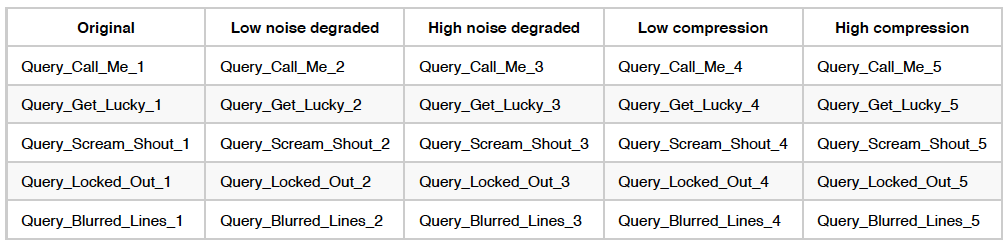

***A.***

The music identification that we develop operates with non-­overlapping frames of **512** samples each. If you have not done so, carry out Assignment ***V.IA*** and ***V.IB*** such that you can convert any of the above songs into a **N**x**M** matrix **XX**. For the purpose of this assignment, `N=512` (the DFT/FFT will be over **N = 512** samples) and **M = 257** (we have 257 non-­overlapping frames). These matrix dimensions match exactly with the number of samples (namely, **131584** samples) in the audio files. Listen to the music represented in the matrix `XX` frame-­by-­frame using the command `sound(XX(:),Fs)`.

***Answer:***

***B.***

The fingerprints of the songs are computed on the magnitude spectrum of the frames. First compute the DFT/FFT of each frame, and next keep only its magnitude. This step has strong similarity to MATLAB HANDS-­ON Assignment ***VII.IC***.

***Answer:***

Rather than working with the magnitudes of the individual DFT/FFT coefficients, the coefficients are grouped together into 17 bands according to the so-­called Bark-­scale. The Bark-­scale is a psychoacoustic scale proposed in 1961 by researchers of the subjective human auditory properties. The original scale represents the human auditory system in 24 critical bands of hearing. Essential to the Bark (and later proposed) scale is that it is a logarithmic scale in frequency.

To obtain a 17 band Bark-­scale, the first 257 (unique) DFT coefficients of a 512-­point DFT are combined in the following way.

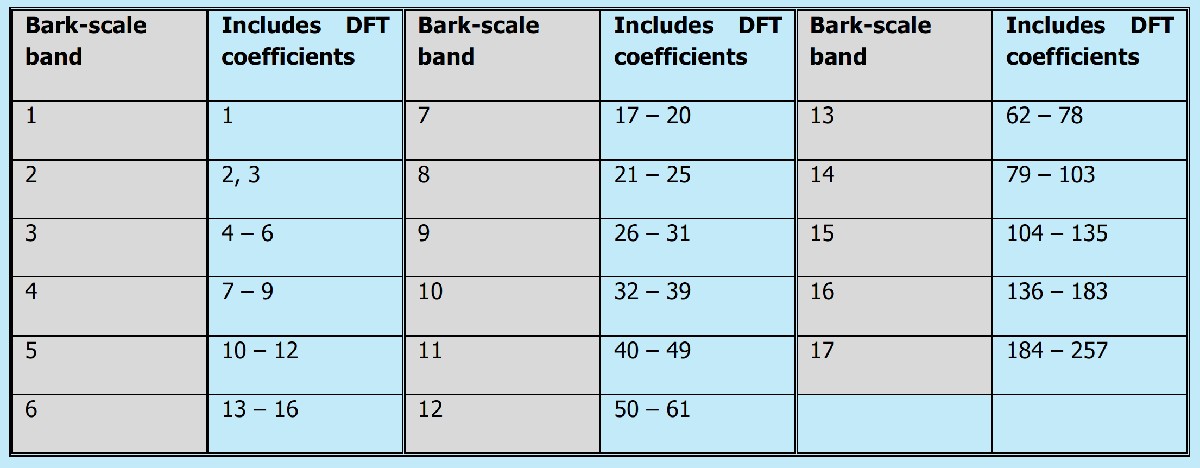

***C.***

The above mapping from DFT coefficient number to Bark scale band is available in the MATLAB matrix ‘`data/bark_scale_band_id.mat`’. Load this matrix using the command `load data/bark_scale_band_id.mat`, and inspect the relation of the loaded matrix `BarkScaleBandID` to the above table.

***Answer:***

***D.***

For each frame, add the (magnitude of the) DFT coefficients that belong to the same Bark-­scale band, yielding a matrix with for each frame **17** values. These values are called *Bark-­scale energies*. Make use of the matrix `BarkScaleBandID` loaded in part ***C***. Store the resulting **17x257** Bark-­scale energies as the matrix **BB**.

***Answer:***

The Bark-­scale energies obtained in the part ***D.*** is now converted/compressed into a binary representation. This representation has been chosen such that it is efficient for database queries and such that it is invariant to changes in loudness and some forms of degradations. The conversion/compression yields a 16x256 elements binary fingerprint in two steps:

- The difference between neighboring Bark-­scale energies is computed, first in the frequency dimension and next in the temporal dimension. If *B(n,m)* represents the 17x257 matrix computed in part ***D***, then the Bark-­scale energy differences are computed as:

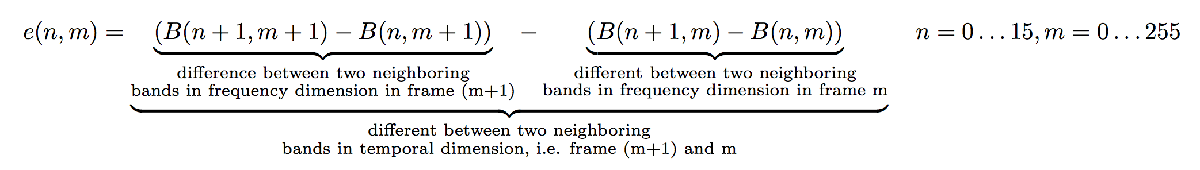

- The 16x256 elements of the binary fingerprint are computed as:


$$b(n, m) = 
\begin{cases}
1 & \text{if } e(n, m) \geq 0\\
0 & \text{if } e(n, m) < 0
\end{cases} \quad n=0\dots15, m=0\dots255$$


***E.***

Implement the above two operations, and compute the fingerprints for (one of) the music clips provided. The figure below illustrates what a binary fingerprint matrix of **16x256** looks like when using the command `pcolor()`$^{(4)}$.

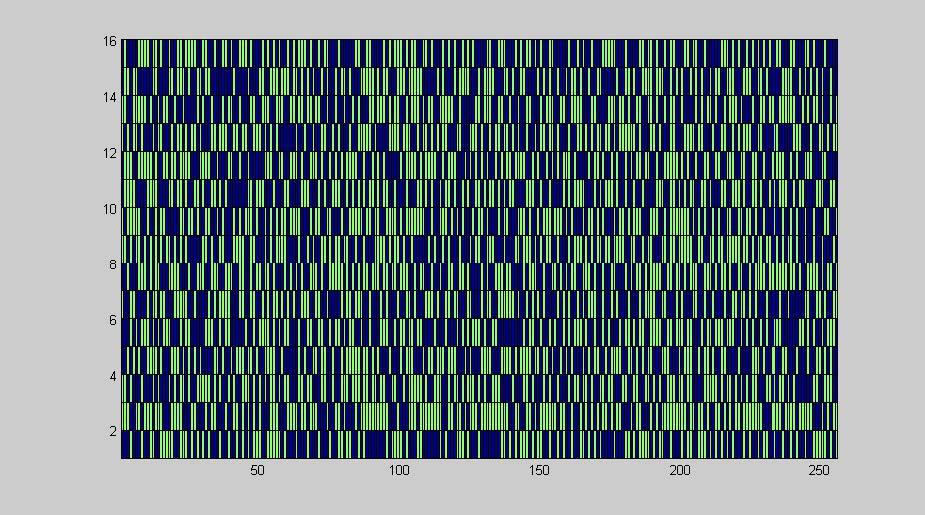

***Answer:***

***F.***

Load the binary fingerprint of the unknown music clip by the command `load data/fingerprint.mat`. 

***Answer:***

Compare this fingerprint with the fingerprints computed from each of the **25** music clips (see above Table). Count and write down the number of differences between the fingerprint pairs, and compute the Bit Error Rate (BER) as **BER=#differences/(16x256)**. 

***Answer:***

From which song was the fingerprint `data/fingerprint.mat` computed? How well can a degraded version of the song be recognized? If you would need to build a detector that decides on basis of the BER if a song is recognized, which BER threshold would you choose for the detector?

***Answer:***

**Completion requirements:**

- Show the fingerprints (as requested in assignment ***E***) for one of the given music samples.

- Explain which song was represented in "`data/fingerprint.mat``"`. Show the BER for each of the music clips in relation to the unknown music clip.

- Explain how you would set a BER threshold to recognize a song in the given dataset.